# 4.4 Open Loop Transfer Function (No Controller)

% Parameters for G

clear;
clc;
close all;

Vin = 5;
L = 42e-6;
C = 230e-6;
R_load = 20;
R_C = 0.5;
w0 = 1/sqrt(L*C) * sqrt(1/(1+R_C/R_load));
Q = (1/w0)*(1/((L/R_load)+C*R_C));
wz = 1/(R_C*C);

G = tf([Vin/wz, Vin], [1/w0^2, 1/(w0*Q), 1]);

% Parameters for K
R_vd1 = 22e3;
R_vd2 = 4.7e3;

K = tf(R_vd2/(R_vd1+R_vd2));

% Transfer Function of the controller
H = tf(1);

% Open-loop Transfer function
G_openloop = G*K*H

G_openloop =
 
       0.0001012 s + 0.8801
  -------------------------------
  9.901e-09 s^2 + 0.0001171 s + 1
 
Continuous-time transfer function.
Model Properties


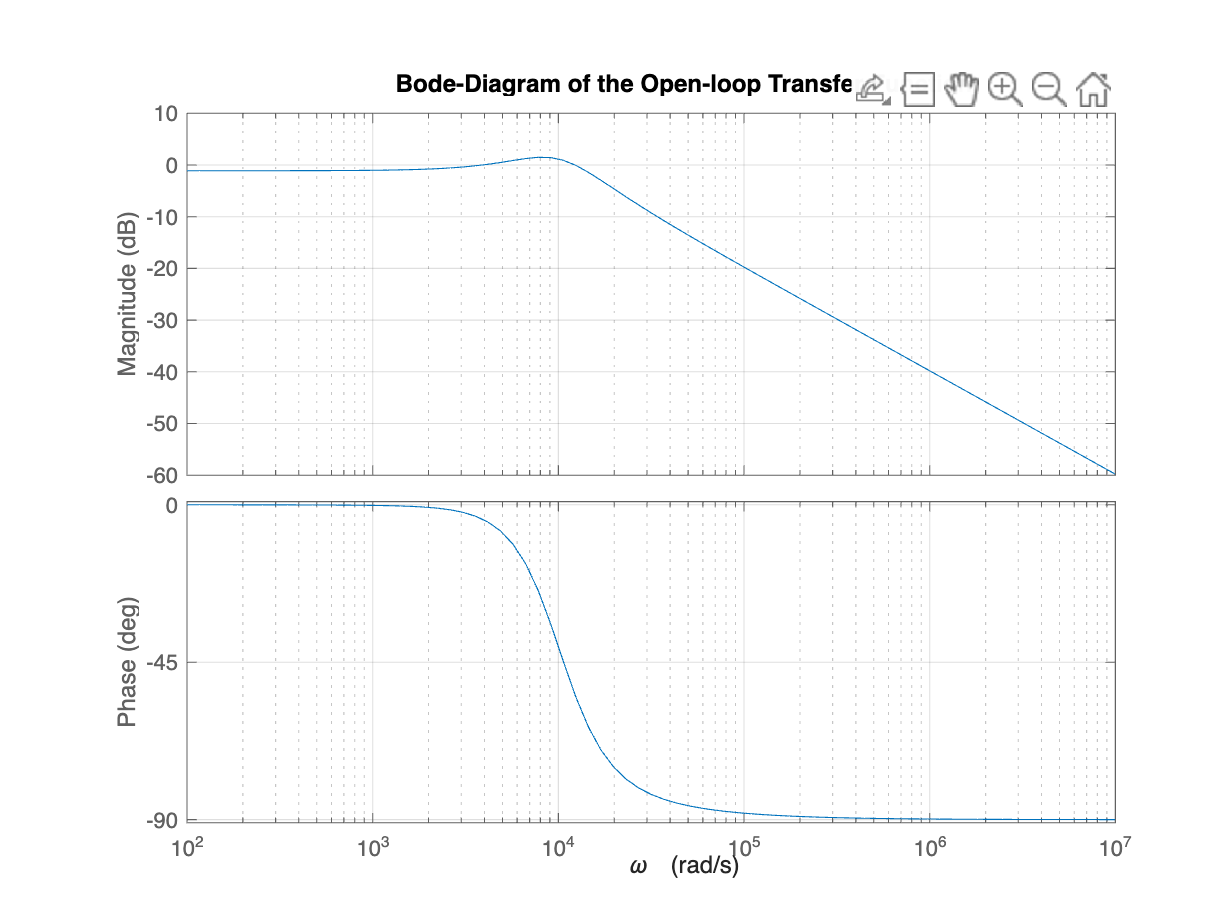


% Plot
figure;
hold on;
%bode(G, {1e2,1e7});
%bode(K, {1e2,1e7});
%bode(H, {1e2,1e7});
bode(G_openloop, {1e2,1e7});
%[Gm, pm, wd2, wd1] = margin(G_openloop)
grid on;
xlabel('\omega');
title('Bode-Diagram of the Open-loop Transfer Function');
%legend('G(s)', 'K(s)', 'H(s)','G_openloop');
hold off;